% LightLevelConversions
%
% Take LED power and convert it to various units.
%
% Some comparisons
%
%     Will's summation paper.  25 nW entering eye at 550nm, paper gives about 828 cd/m2,
%     for 1.2 by 1.2 degree field, 7.75 mm pupil.  We get about 984 here.  This
%     depends on exact pupil size, which is used to convert power entering eye
%     to retinal irradiance.
%     LEDPeaksNm = 550;
%     LEDPowerUW = 25e-3;
%
%     Derek calculation.  6.7 uW entering eye for 4 deg square stimulus for
%     some broadband stimulus.  Gets 100-160 cd/m2 luminance.

% History:
%    01/12/24  dhb, fh     Started to write version to understand S cone acuity.
%                          We began with LightLevelConversiions1 from the
%                          SACC project.

%% Clear and close
clear; close all

%% Define the wavelength spacing that we will work with
S = [380 1 401];
if (S(2) ~= 1)
    error('We are assuming 1 nm spacing');
end
wls = SToWls(S);

%% Point at directory with spectra
projectName = 'SConeSpatial';
% LEDMeasDateStr = '2021-07-08';
% LEDSpectraDir = fullfile(getpref(projectName,'LEDSpectraDir'),LEDMeasDateStr);

% Spectral data.
%
% May 5, 2022 is 3 mm pupil data.
% Options for mode are 'Normal' and 'SteadyOn'
mode = 'Normal';
LEDInFileName = ['FullWhite' mode 'SPD'];
LEDOutFileName = ['FullWhite' mode 'SPD_UW'];
XLSOutFileName = ['FullWhite' mode];
LEDMeasDateStr = '2022-05-05';
LEDSpectraDir = fullfile(getpref(projectName,'CheckDataFolderSACC'));
inFilename = fullfile(LEDSpectraDir,append(LEDInFileName,'_',LEDMeasDateStr,'.mat'));
outFilename = fullfile(LEDSpectraDir,append(LEDOutFileName,'_',LEDMeasDateStr,'.mat'));
xlsFilename = fullfile(LEDSpectraDir,append(XLSOutFileName,'_',LEDMeasDateStr,'.xlsx'));

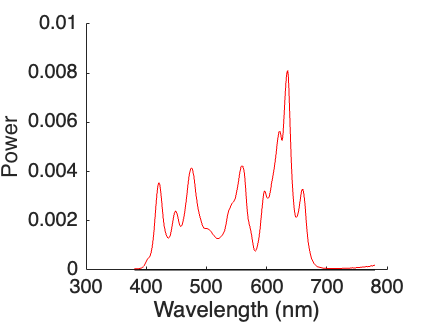

%% Get full on spectrum
white = load(inFilename);
spd_w = SplineSpd(white.S, white.spd, S);
spd_blk = zeros(size(spd_w));
figure; clf; hold on
plot(wls,spd_w,'r');
plot(wls,spd_blk,'k');
xlabel('Wavelength (nm)');
ylabel('Power');

%% Convert spectrum to power at the cornea
%
% Default k-factor here is for 3 mm pupil. Slightly smaller
% than the 0.01 we got for the 4 mm pupil.  A pupil size
% dependence seems plausible.
k = GetWithDefault('Enter PR-670 to relative to mW corneal power k factor (mW units)',0.0089);
spd_w = k*spd_w;
spd_blk = k*spd_blk;
mWToUW = 1000;

%% Get the maximum spd in uW per wavelength band
maxSpdUW = mWToUW*(spd_w-spd_blk);

% Power in maxSpd *assumes 1 nm spacing enforced above)
maxSpdPowerUW = sum(maxSpdUW);

%% Get inputs and put into common format
pupilDiamMm = GetWithDefault('Enter pupil diameter in mm',3);
eyeLengthMm = GetWithDefault('Enter assumed eye length in mm',16.6832);
LENGTHORAREA = GetWithDefault('Enter stimulus side (1), stimulus diameter (2), or stimulus area (3)?',3);
switch (LENGTHORAREA)
    case 1
        rawStimulusSideDegIn = GetWithDefault('Enter square stimulus side in deg',12);
        stimulusAreaDegrees2 = rawStimulusSideDegIn^2;
    case 2
        rawStimulusSideDegIn = GetWithDefault('Enter circular stimulus diameter in deg',1.8);
        stimulusAreaDegrees2 = pi*(rawStimulusSideDegIn/2)^2;
    case 3
        %stimulusAreaDegrees2 = GetWithDefault('Enter stimulus area in square degrees',7.44*13.30);
        %stimulusAreaDegrees2 = GetWithDefault('Enter stimulus area in square degrees',7.6344*13.592);
        stimulusAreaDegrees2 = GetWithDefault('Enter stimulus area in square degrees',7.6*13.511);
end


$$A={\pi \left(\frac{d}{2}\right)}^2$$


$d:$ stimulus diameter (deg)

$A:$ stimulus area (deg)

% Utility calculations
pupilAreaMm2 = pi*((pupilDiamMm/2)^2);
pupilAreaCm2 = pupilAreaMm2*(10^-2);
eyeLengthCm = eyeLengthMm*(10^-1);
degPerMm = RetinalMMToDegrees(1,eyeLengthMm);
degPerCm = degPerMm*10;

% Convert retinal area from deg2 to cm2
stimulusAreaCm2 = stimulusAreaDegrees2/(degPerCm^2);

% Accept either retinal illuminance, corneal illuminance, or power entering
% eye.  Convert to retinal and corneal irradiance for further computations.
RETORCORN = GetWithDefault('Enter retinal irradiance (1), corneal irradiance (2), or power entering eye (3)?',3);
switch (RETORCORN)
    case 1
        IRRADUNITS = GetWithDefault('Enter retinal irradiance in units of  microwatts/cm2 (1) or microwatts/deg2 (2)?',1);
        switch (IRRADUNITS)
            case 1
                rawRetIrradianceMicrowattsPerCm2In = GetWithDefault('Enter retinal illuminance in microwatts/cm2',25.5);
            case 2
                rawRetIrradianceMicrowattsPerDeg2In = GetWithDefault('Enter retinal illuminance in microwatts/deg2',0.5);
                rawRetIrradianceMicrowattsPerCm2In = rawRetIrradianceMicrowattsPerDeg2In*(degPerCm^2);
        end
        rawCornIrradianceMicrowattsPerCm2In = rawRetIrradianceMicrowattsPerCm2In*stimulusAreaCm2/pupilAreaCm2;
    case 2
        rawCornIrradianceMicrowattsPerCm2In = GetWithDefault('Enter corneal illuminance in microwatts/cm2',25.5);
        rawRadianceMicrowattsPerCm2Sr = CornIrradianceAndDegrees2ToRadiance(rawCornIrradianceMicrowattsPerCm2In,stimulusAreaDegrees2);
        rawRetIrradianceMicrowattsPerCm2In = RadianceAndPupilAreaEyeLengthToRetIrradiance(rawRadianceMicrowattsPerCm2Sr,S,pupilAreaCm2,eyeLengthCm);
    case 3
        rawPowerIntoEyeIn = GetWithDefault('Enter power entering eye in microwatts',maxSpdPowerUW);
        rawCornIrradianceMicrowattsPerCm2In = rawPowerIntoEyeIn/pupilAreaCm2;
        rawRadianceMicrowattsPerCm2Sr = CornIrradianceAndDegrees2ToRadiance(rawCornIrradianceMicrowattsPerCm2In,stimulusAreaDegrees2);
        %rawRadianceMicrowattsPerCm2Sr1 = CornIrradianceAndDegrees2ToRadiance(rawCornIrradianceMicrowattsPerCm2In/stimulusAreaDegrees2,1);
        rawRetIrradianceMicrowattsPerCm2In = RadianceAndPupilAreaEyeLengthToRetIrradiance(rawRadianceMicrowattsPerCm2Sr,S,pupilAreaCm2,eyeLengthCm);  

end
% clear rawRadianceMicrowattsPerCm2Sr;

**Retinal Irradiance**: This refers to the amount of light energy (usually measured in watts or microwatts) per unit area that reaches the retina, the light-sensitive layer at the back of the eye. It's a measure of the intensity of light after it has passed through the eye's optical components, such as the cornea, aqueous humor, lens, and vitreous humor.


$$I_{\mathrm{retinal}\;\left\lbrack \mathrm{watts}/{\mathrm{cm}}^2 \right\rbrack } =$$

$$I_{\mathrm{retinal}\;\left\lbrack \mathrm{watts}/\deg^2 \right\rbrack } *34\ldotp {3425}^2$$



$$I_{\mathrm{corneal}\;\left\lbrack \mathrm{watts}/{\mathrm{cm}}^2 \right\rbrack } =I_{\mathrm{retinal}\;\left\lbrack \mathrm{watts}/{\mathrm{cm}}^2 \right\rbrack } *\frac{A_{\left\lbrack {\mathrm{cm}}^2 \right\rbrack } }{p_{\left\lbrack {\mathrm{cm}}^2 \right\rbrack } }$$


$p:$ pupil size

**Corneal Irradiance**: In contrast, corneal irradiance measures the light energy per unit area falling on the cornea, which is the transparent front part of the eye. This measurement is taken before the light passes through any of the eye's internal structures.

**Power entering the eye**: This refers to the total amount of light energy (measured in watts or microwatts) that is entering the eye. It's a broader measure than either retinal or corneal irradiance because it doesn't specifically focus on the light intensity per unit area (like irradiance does), but rather on the total light power entering the eye.


$$I_{\mathrm{corneal}\;\left\lbrack \mathrm{watts}/{\mathrm{cm}}^2 \right\rbrack } =\frac{E_{\left\lbrack \mathrm{watts}\right\rbrack } }{p_{\left\lbrack {\mathrm{cm}}^2 \right\rbrack } }$$



$$I_{\mathrm{retinal}\;\left\lbrack \mathrm{watts}/{\mathrm{cm}}^2 \right\rbrack } =\frac{p_{\left\lbrack {\mathrm{cm}}^2 \right\rbrack } }{l_{\left\lbrack {\mathrm{cm}}^2 \right\rbrack } }*\frac{I_{\mathrm{corneal}\;\left\lbrack \mathrm{watts}/{\mathrm{cm}}^2 \right\rbrack } }{A_{\left\lbrack {\mathrm{rad}}^2 \right\rbrack } }$$


%% Save out the corneal power in uW/nm as well as pupil diameter in mm
maxSpdUWPerCm2 = maxSpdUW/(pi*(pupilDiamMm/20)^2);
save(outFilename,'wls','maxSpdUW','maxSpdUWPerCm2','pupilDiamMm','stimulusAreaDegrees2');

%% Pupil adjustment factor for Ansi MPE 
mpePupilDiamMm = 3;
mpePupilDiamMm  = GetWithDefault('Enter ANSI 2007 MPE caclulations assumed pupil diameter in mm',mpePupilDiamMm );
pupilAdjustFactor = (pupilDiamMm/mpePupilDiamMm).^2;
 
%% Given that we have retinal irradiance, corneal irradiance, the pupil area, and the stimulus area ...
%
% it is easy to check the retinal irradiance.
retIrradianceMicrowattsPerDeg2Check = rawCornIrradianceMicrowattsPerCm2In*pupilAreaCm2/stimulusAreaDegrees2;
retIrradianceMicrowattsPerCm2Check = retIrradianceMicrowattsPerDeg2Check/(0.01*DegreesToRetinalMM(1,eyeLengthCm*10)^2);
if (abs(rawRetIrradianceMicrowattsPerCm2In-retIrradianceMicrowattsPerCm2Check)/retIrradianceMicrowattsPerCm2Check > 0.05)
    error('Do not get same retinal irradiance two different ways');
end

%% Get retinal irradiance as spectral function
%
% We want sum over wavelength to be equal to the specified value
retIrradianceMicrowattsPerCm2In = rawRetIrradianceMicrowattsPerCm2In*maxSpdUW/sum(maxSpdUW);
retIrradianceMicrowattsPerDeg2In = retIrradianceMicrowattsPerDeg2Check*maxSpdUW/sum(maxSpdUW);
retIrradianceWattsPerDeg2In = retIrradianceMicrowattsPerDeg2In/1e6;

%% Convert to some other units for convenience
retIrradianceMilliwattsPerCm2In = retIrradianceMicrowattsPerCm2In*(10^-3);
retIrradianceWattsPerCm2In = retIrradianceMilliwattsPerCm2In*(10^-3);
retIrradianceWattsPerUm2In = retIrradianceWattsPerCm2In*(10^-8);


%% Load CIE functions.   
load T_xyz1931
T_xyz = SplineCmf(S_xyz1931,683*T_xyz1931,S);

% Compute photopic trolands from retinal irradiance
for ii = 1:length(wls)
    trolandsCheckSpd(ii) = PowerToTrolands(wls(ii),retIrradianceWattsPerDeg2In(ii),S,T_xyz/683);
end
trolandsCheck = sum(trolandsCheckSpd);

%% Load cone spectral sensitivities
load T_cones_ss2
T_cones = SplineCmf(S_cones_ss2,T_cones_ss2,S);

%% Load in a directly measured sunlight through window
% and off piece of white paper towel on floor for comparison.
% Surely that is safe to look at.
load spd_phillybright
spd_phillybright = SplineSpd(S_phillybright,spd_phillybright,S);
photopicLuminancePhillyBrightCdM2 = T_xyz(2,:)*spd_phillybright;


%% Estimate power near 790 in sunlight
% Quick and dirty.  Set spd_phillybright so that there is power
% in a band near 790 to the power measured at 780; 780 is the upper
% limb of the radiance measurement we have.
index780 = find(wls == 780);
power780 = spd_phillybright(index780);
indices = find(wls >= 770 & wls <= 810);
spd_790bright = zeros(size(spd_phillybright));
spd_790bright(indices) = power780;

%% Compute irradiance to equivalent radiance
%
% We can find the radiance of an external stimulus that
% produces the spectral irradiance specified.  This is
% useful for doing colorimetric calculations that are
% set up assuming that we begin with radiance.  There
% is no loss of generality here, although the calculations
% do depend on assumptions about pupil area and eye length.

% Do the conversion
radianceMilliwattsPerCm2Sr = RetIrradianceAndPupilAreaEyeLengthToRadiance(retIrradianceMilliwattsPerCm2In,S,pupilAreaCm2,eyeLengthCm);
radianceMicrowattsPerCm2Sr = radianceMilliwattsPerCm2Sr*(10^3);
radianceWattsPerCm2Sr = radianceMilliwattsPerCm2Sr*(10^-3);
radianceWattsPerM2Sr = radianceWattsPerCm2Sr*(10^4);
radianceQuantaPerM2SrSec = EnergyToQuanta(S,radianceWattsPerM2Sr);

% Check by converting back using a different routine
retIrradianceWattsPerUm2 = RadianceToRetIrradiance(radianceWattsPerM2Sr,S,pupilAreaMm2,eyeLengthMm);
retIrradianceWattsPerM2 = retIrradianceWattsPerUm2*(10^12);
retIrradianceWattsPerCm2 = retIrradianceWattsPerUm2*(10.^8);
retIrradianceMilliwattsPerCm2 = retIrradianceWattsPerCm2*(10^3);
retIrradianceMicrowattsPerCm2 = retIrradianceMilliwattsPerCm2*(10^3); 
tolerance = 1e-8;
if (max(abs(retIrradianceMicrowattsPerCm2(:)-retIrradianceMicrowattsPerCm2In(:))) > tolerance)
    error('Failure to go there and back');
end

%% Convert retinal irradiance to trolands, etc.
irradianceScotTrolands = RetIrradianceToTrolands(retIrradianceWattsPerUm2, S, 'Scotopic', [], num2str(eyeLengthMm));
irradiancePhotTrolands = RetIrradianceToTrolands(retIrradianceWattsPerUm2, S, 'Photopic', [], num2str(eyeLengthMm));
retIrradianceQuantaPerUm2Sec = EnergyToQuanta(S,retIrradianceWattsPerUm2);
retIrradianceQuantaPerCm2Sec = (10.^8)*retIrradianceQuantaPerUm2Sec;
retIrradianceQuantaPerDeg2Sec = (degPerMm^2)*(10.^-2)*retIrradianceQuantaPerCm2Sec;

% Yet more units
photopicLuminanceCdM2 = T_xyz(2,:)*radianceWattsPerM2Sr;


%% Get trolands another way.  For scotopic trolands, this just uses scotopic vlambda (in PTB as T_rods)
% and the magic factor of 1700 scotopic lumens per Watt from Wyszecki & Stiles (2cd edition),
% p. 257.  (This is the analog of 683 photopic lumens per Watt.  Then apply formula from
% page 103 of same book.
%
% Same idea for photopic trolands, although we already have luminance in cd/m2 from above so
% we can short cut a little.
%
% The agreement is good to integer scotopic trolands and I'm will to write off the rest
% as round off error.
load T_rods
T_scotopicVlambda = SplineCmf(S_rods,T_rods,S);
irradianceScotTrolands_check = pupilAreaMm2*1700*(T_scotopicVlambda*radianceWattsPerM2Sr);
irradiancePhotTrolands_check = pupilAreaMm2*photopicLuminanceCdM2;

%% Compute spectral corneal irradiance
%
% Make sure total corneal irradiance matches what we computed above
cornealIrradianceMicrowattsPerCm2 = RadianceAndDegrees2ToCornIrradiance(radianceMicrowattsPerCm2Sr,stimulusAreaDegrees2);
switch (RETORCORN)
    case 2
        if (abs(sum(cornealIrradianceMicrowattsPerCm2)-rawCornIrradianceMicrowattsPerCm2In) > tolerance)
            error('Corneal irradiance computation did not invert');
        end
end
cornealIrradianceWattsPerM2 = cornealIrradianceMicrowattsPerCm2*(10^-6)*(10^4);
cornealIrradianceWattsPerCm2 = (10.^-4)*cornealIrradianceWattsPerM2;
cornealIrradianceUWattsPerCm2 = (10.^6)*cornealIrradianceWattsPerCm2;
cornealIrradianceQuantaPerCm2Sec = EnergyToQuanta(S,cornealIrradianceWattsPerCm2);
if (max(abs(maxSpdUWPerCm2-cornealIrradianceUWattsPerCm2)) > 1e-10)
    error('Inconsistency in corneal irradiance');
end

%% Report on stimulus
fprintf('\n');
fprintf('  * Analyzing light levels as input\n');
fprintf('  * Stimulus radiance %0.1f log10 watts/[m2-sr], %0.1f log10 watts/[cm2-sr]\n',log10(sum(radianceWattsPerM2Sr)),log10(sum(radianceWattsPerCm2Sr)));
fprintf('  * Stimulus luminance %0.1f candelas/m2\n',photopicLuminanceCdM2);
fprintf('    * For comparison, luminance directly from PR spectrum: %01.f cd/m2\n',T_xyz(2,:)*maxSpdUW);
fprintf('    * For comparison, sunlight in Philly: %0.1f cd/m2\n',photopicLuminancePhillyBrightCdM2);
fprintf('    * For comparison, sunlight in Philly: %0.1f log10 watts/[m2-sr], %0.1f log10 watts/[cm2-sr]\n',log10(sum(spd_phillybright)),log10(sum(spd_phillybright/10000)));
fprintf('    * For comparison, sunlight in Philly near 790 nm: %0.1f log10 watts/[m2-sr], %0.1f log10 watts/[cm2-sr]\n',log10(sum(spd_790bright)),log10(sum(spd_790bright/10000)));
fprintf('  * Stimulus %0.0f (check val %0.0f) scotopic trolands, %0.0f photopic trolands (check val %0.0f), (W+S check val %0.0f)\n',irradianceScotTrolands,irradianceScotTrolands_check,...
    irradiancePhotTrolands,irradiancePhotTrolands_check,trolandsCheck);
fprintf('  * Stimulus %0.1f log10 scotopic trolands, %0.1f log10 photopic trolands\n',log10(irradianceScotTrolands),log10(irradiancePhotTrolands));
fprintf('  * Stimulus retinal irradiance %0.1f log10 watts/cm2\n',log10(sum(retIrradianceWattsPerCm2)));
fprintf('  * Stimulus retinal irradiance %0.1f log10 quanta/[cm2-sec]\n',log10(sum(retIrradianceQuantaPerCm2Sec)));
fprintf('  * Stimulus retinal irradiance %0.1f log10 quanta/[deg2-sec]\n',log10(sum(retIrradianceQuantaPerDeg2Sec)));
fprintf('  * Stimulus corneal irradiance %0.1f log10 watts/cm2\n',log10(sum(cornealIrradianceWattsPerCm2)));
fprintf('  * Stimulus corneal irradiance %0.1f log10 quanta/[cm2-sec]\n',log10(sum(cornealIrradianceQuantaPerCm2Sec)));
   
%% Get receptor sensitivities and compute isomerization rates, fraction bleached
%
% We'll be fancy and use the SilentSubstitionToolbox, since we
% see that as the future of this sort of calculation.
fieldSizeDeg = 2;
observerAgeYears = 32;
receptorObj = SSTReceptorHuman('obsAgeInYrs', observerAgeYears, 'fieldSizeDeg', fieldSizeDeg, 'obsPupilDiameter', pupilDiamMm, 'doPenumbralConesTrueFalse', false, 'verbosity', 'none');
nReceptors = length(receptorObj.labels);

% LMS cones should be 1 to 3. Trust but verify
% 
% A key variable is inner segment diameter, about which there is reasonable
% uncertainty outside the fovea.
fprintf('\nComputing cone isomerizations and bleaching\n');
for rr = 1:3
    % Check cone types and set numbers.  This is set up to allow
    % eccentricity specific cone IS diameters, but the specific
    % numbers are pretty rough and ready.  May want to update SST
    % to carry these numbers around.
    switch (rr)
        case 1
            if (~strcmp(receptorObj.labels{rr},'LCone'))
                error('L cone is not where we expect it');
            end
            if (fieldSizeDeg <= 4)
                ISdiameterUm(rr) = PhotoreceptorDimensions('FovealLCone','ISdiam','Human','Rodieck');
            else
                ISdiameterUm(rr) = PhotoreceptorDimensions('LCone','ISdiam','Human','Webvision');
            end
        case 2
            if (~strcmp(receptorObj.labels{rr},'MCone'))
                error('M cone is not where we expect it');
            end
            if (fieldSizeDeg <= 4)
                ISdiameterUm(rr) = PhotoreceptorDimensions('FovealMCone','ISdiam','Human','Rodieck');
            else
                ISdiameterUm(rr) = PhotoreceptorDimensions('MCone','ISdiam','Human','Webvision');
            end
        case 3
            if (~strcmp(receptorObj.labels{rr},'SCone'))
                error('S cone is not where we expect it');
            end
            if (fieldSizeDeg <= 4)
                ISdiameterUm(rr) = PhotoreceptorDimensions('FovealSCone','ISdiam','Human','Rodieck');
            else
                ISdiameterUm(rr) = PhotoreceptorDimensions('SCone','ISdiam','Human','Webvision');
            end
    end
    
    % Get fundamentals in form that expects radiance in quantal units and
    % is in terms of probability of isomerization per incidenct quantum.
    T_quantalIsomerizations = SplineCmf(receptorObj.S,receptorObj.T.T_quantalIsomerizations(rr,:),S);
    
    % Need a cone collecting area. 
    ISareaUm2 = pi*(ISdiameterUm(rr)/2)^2;
    
    % Get isom/sec and bleaching
    isomerizationsSec(rr) = ISareaUm2*T_quantalIsomerizations*retIrradianceQuantaPerUm2Sec;
    fractionBleachedFromIsom(rr) = ComputePhotopigmentBleaching(isomerizationsSec(rr),'cones','isomerizations','Boynton');
    fprintf('    * %s, inner segment diam %0.2f um, isom/sec %0.2f, fraction bleached %0.2f\n',receptorObj.labels{rr},ISdiameterUm(rr),isomerizationsSec(rr),fractionBleachedFromIsom(rr));
end

%% As a check, ballpark isomerization rate from luminance
%
% Get IS diamter in minutes as 2-1 average of LM values above.
% This agreement is order of magnitude correct.
ISdiameterMinutes = 60*((2*ISdiameterUm(1)+ISdiameterUm(2))/3)/300;
if (exist('IsomerizationsFromLuminanceGeisler','file'))
    isomerizationsFromLuminance = IsomerizationsFromLuminanceGeisler(photopicLuminanceCdM2,1,pupilDiamMm, 'coneApertureDiameterMinutes', ISdiameterMinutes);
    fprintf('    * Isom/sec from luminance: %0.2f, 2-1 average of LM isom/sec: %0.2f\n',isomerizationsFromLuminance,(2*isomerizationsSec(1) + isomerizationsSec(2))/3);
end

% Use SST call directly.
%
% This prints out values for isomerizations that match the above,
% and also does the call into the routine that computes photopigment
% bleaching.
%
% I probably would not have written the above if I had remembered that this
% already existed.
[fractionBleachedFromIsom, fractionBleachedFromIsomHemo] = GetConeFractionBleachedFromSpectrum(S, radianceWattsPerM2Sr, fieldSizeDeg, observerAgeYears, pupilDiamMm, ...
    [], true);

%% Get MPE from as a function of wavelength.  For each wavelength,
% take minimum radiance over specified sizes and durations.

% Specify what parameters to test
minLogSize = -1; maxLogSize = 2;
minLogDuration = -1; maxLogDuration = 4;
minLogYRad = -3; maxLogYRad = 2;
minLogYIrrad = -5; maxLogYIrrad = 0;
minLogYIntRad = 0; maxLogYIntRad = 3;
minLogYRadExp = -4; maxLogYRadExp = -1;

% MPE calcls
measuredWls = wls;
index = find(measuredWls >= 400);
stimulusWavelengthsNm = measuredWls(index);
stimulusSizesDeg = logspace(minLogSize,maxLogSize,5);
stimulusDurationsSec = logspace(minLogDuration,maxLogDuration,5);
%fprintf('Computing MPE over wavelengths from %0.1f to %0.1f deg\n',min(stimulusWavelengthsNm),max(stimulusWavelengthsNm));
clear MPELimitIntegratedRadiance_JoulesPerCm2Sr MPELimitRadiance_WattsPerCm2Sr MPELimitCornealIrradiance_WattsPerCm2 MPELimitCornealRadiantExposure_JoulesPerCm2
for w = 1:length(stimulusWavelengthsNm)
    stimulusWavelengthNm = stimulusWavelengthsNm(w);
    if (rem(w,10) == 0)  
        %fprintf('\tComputing minimum MPE for wavelength %d nm\n',stimulusWavelengthNm);
    end
    MPELimitIntegratedRadiance_JoulesPerCm2Sr(w) = Inf;
    MPELimitRadiance_WattsPerCm2Sr(w) = Inf;
    MPELimitCornealIrradiance_WattsPerCm2(w) = Inf;
    MPELimitCornealRadiantExposure_JoulesPerCm2(w) = Inf;
    for s = 1:length(stimulusSizesDeg)
        stimulusSizeDeg = stimulusSizesDeg(s);
        stimulusSizeMrad = DegToMrad(stimulusSizeDeg);
        for t = 1:length(stimulusDurationsSec)
            stimulusDurationSec = stimulusDurationsSec(t);
            
            % Compute MPE.  We don't understand how the cone limit computations fit in with
            % the standard, or not.  So, we run it both ways and take the lower limit returned.
            [temp1, temp2, temp3, temp4] = ...
                AnsiZ136MPEComputeExtendedSourceLimit(stimulusDurationSec,stimulusSizeDeg,stimulusWavelengthNm,0);
            [temp5, temp6, temp7, temp8] = ...
                AnsiZ136MPEComputeExtendedSourceLimit(stimulusDurationSec,stimulusSizeDeg,stimulusWavelengthNm,1);
            if (temp5 < temp1)
                temp1 = temp5;
            end
            if (temp6 < temp2)
                temp2 = temp6;
            end
            if (temp7 < temp3)
                temp3 = temp7;
            end
            if (temp8 < temp4)
                temp4 = temp8;
            end
            clear temp5 temp6 temp7 temp8
            
            % Store minimum at each wavelength.
            if (temp1 < MPELimitIntegratedRadiance_JoulesPerCm2Sr(w))
                MPELimitIntegratedRadiance_JoulesPerCm2Sr(w) = temp1;
            end
            if (temp2 < MPELimitRadiance_WattsPerCm2Sr(w))
                MPELimitRadiance_WattsPerCm2Sr(w) = temp2;
            end
            if (temp3 < MPELimitCornealIrradiance_WattsPerCm2(w))
                MPELimitCornealIrradiance_WattsPerCm2(w) = temp3;
            end
            if (temp4 < MPELimitCornealRadiantExposure_JoulesPerCm2(w))
                MPELimitCornealRadiantExposure_JoulesPerCm2(w) = temp4;
            end
        end
    end
end

%% Find how much total radiance we could tolerate if all our power was at the 
% wavelength with minimum MPE.
minMPERadiance = min(MPELimitRadiance_WattsPerCm2Sr(:));
fprintf('\n');
fprintf('  * Compute ANSI 2007 MPE as a function of wavelength.  For each wavelength, took minimum over size and duration\n');
fprintf('    * Size range: %0.1f to %0.1f degrees\n',min(stimulusSizesDeg),max(stimulusSizesDeg));
fprintf('    * Duration range: %0.1f to %0.1f seconds\n',min(stimulusDurationsSec),max(stimulusDurationsSec));
fprintf('  * Minimum ANSI MPE value over wavelengths: radiance %0.1f log W/[cm2-sr]\n',log10(minMPERadiance));
fprintf('    * Compare with total stimulus radiance %0.1f log  W/[cm2-sr]\n',log10(sum(radianceWattsPerCm2Sr)));
fprintf('    * Compare with total pupil adjusted radiance %0.1f log  W/[cm2-sr]\n',log10(sum(radianceWattsPerCm2Sr))+log10(pupilAdjustFactor));
fprintf('    * Pupil adjustment assumes observer pupil diameter of %0.1f mm, MPE standard diameter of %0.1f mm\n',pupilDiamMm,mpePupilDiamMm);
fprintf('\n');

%% Sum over wavelength of power divided by MPE
% Could put this back in, but would have to think
% a bit harder about wavelength spacing adjustment.
%
% index = find(stimulusWavelengthsNm >= 400);
% deltaMeasuredWls = measuredWls(2)-measuredWls(1);
% deltaMPEWls = stimulusWavelengthsNm(2)-stimulusWavelengthsNm(1);
% MPERatioSum = 0;
% for i = 1:length(stimulusWavelengthsNm)
%     index = find(measuredWls == stimulusWavelengthsNm(i));
%     MPERatioSum = MPERatioSum + radianceWattsPerCm2Sr(index)/MPELimitRadiance_WattsPerCm2Sr(i);
% end
% fprintf('MPERatioSum = %0.4f\n',MPERatioSum*deltaMPEWls/deltaMeasuredWls);

%% Now compare to the ISO Standard
stimulusDurationForISOMPESecs = 60*120;
[IsOverLimit,ISO2007MPEStruct] = ISO2007MPECheckType1ContinuousRadiance(S,radianceWattsPerM2Sr,stimulusDurationForISOMPESecs,stimulusAreaDegrees2,eyeLengthMm);
fprintf('  * ISO MPE Analysis\n');
ISO2007MPEPrintAnalysis(IsOverLimit,ISO2007MPEStruct);
fprintf('  * Assumed duration seconds %0.1f, hours %0.1f\n',stimulusDurationForISOMPESecs,stimulusDurationForISOMPESecs/3600);

%% Write xlsx file
writematrix([wls maxSpdUW maxSpdUWPerCm2],xlsFilename);

